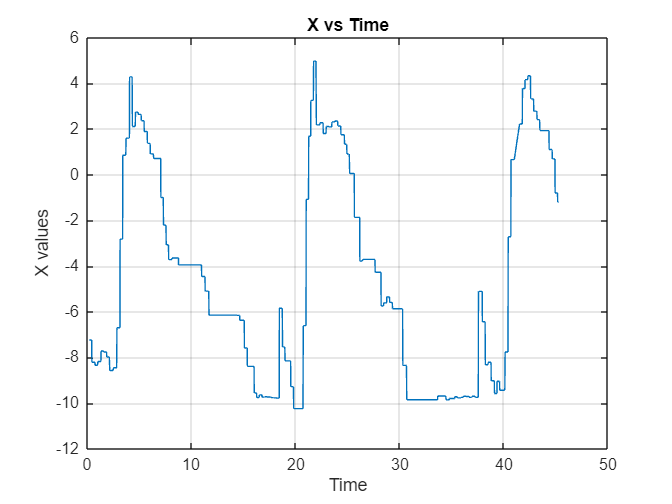

    csv_data = readtable('tracking_data.csv');
    
    t = csv_data{:,1};
    x = csv_data{:,2};
    y=csv_data{:,3};
    true_x=csv_data{:,4}; 
    true_y=csv_data{:,5}; 

    % t = t(1:20);
    % x = x(1:20);
    % y = y(1:20); 
    % true_x = true_x(1:20);
    % true_y = true_y(1:20);


    
    error_x = true_x - x;  
    error_y=true_y-y;
    
    plot(t, x);
    xlabel('Time');
    ylabel('X values');
    title('X vs Time');
    grid on;  

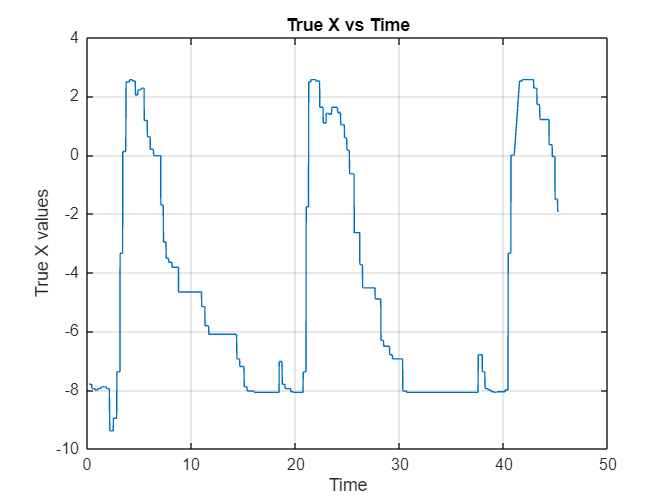

    
    plot(t, true_x);
    xlabel('Time');
    ylabel('True X values');
    title('True X vs Time');
    grid on;  

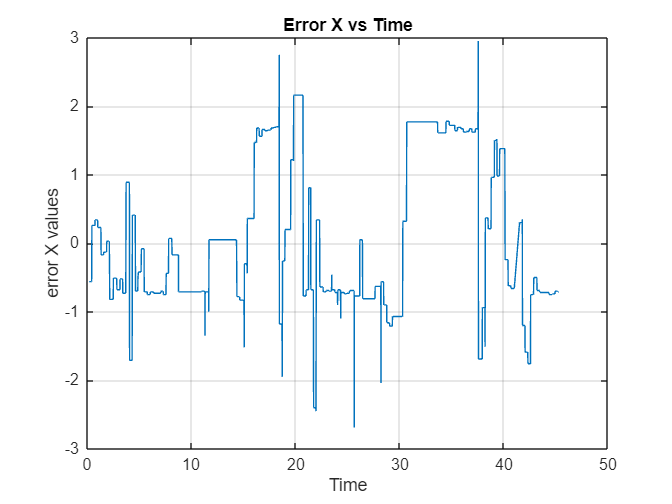

    
    plot(t, error_x);
    xlabel('Time');
    ylabel('error X values');
    title('Error X vs Time');
    grid on;    

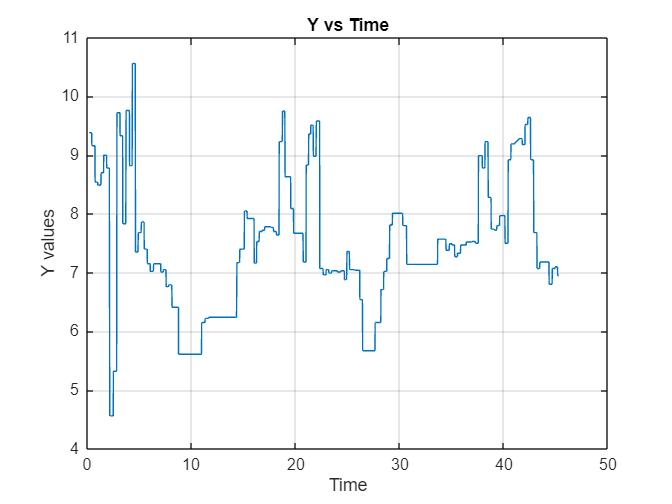

    
    plot(t, y);
    xlabel('Time');
    ylabel('Y values');
    title('Y vs Time');
    grid on;  

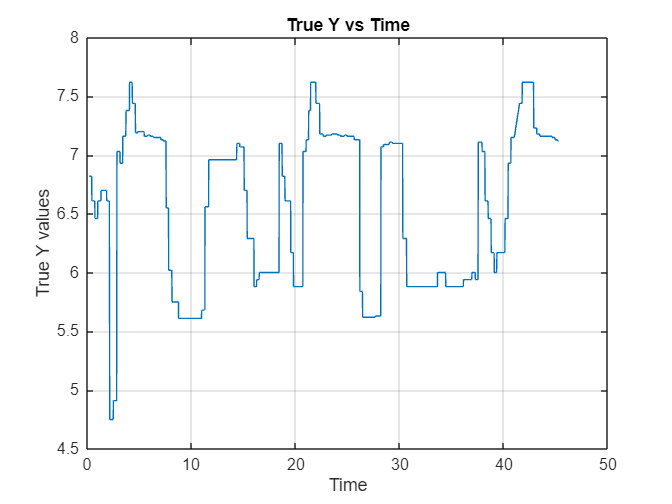

    
    plot(t, true_y);
    xlabel('Time');
    ylabel('True Y values');
    title('True Y vs Time');
    grid on;  

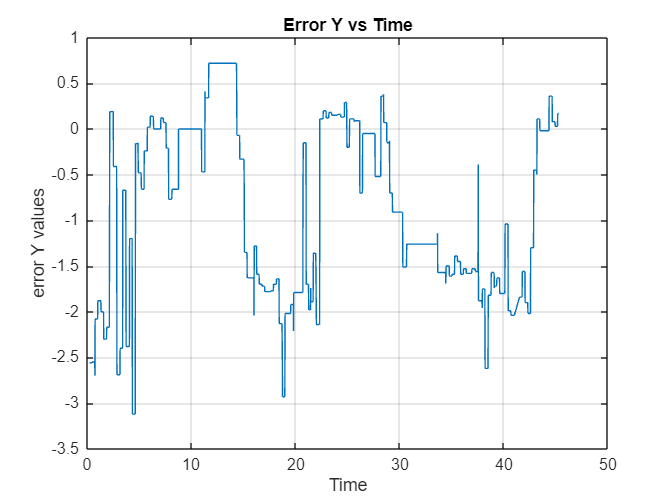

    
    plot(t, error_y);
    xlabel('Time');
    ylabel('error Y values');
    title('Error Y vs Time');
    grid on;   

    
    
    Ts = t(2) - t(1); % assuming uniform sampling
    data = iddata(y, true_y, Ts); % measured output, input, sampling time
    
    sys1=tfest(data,1,1); 
    %PID tuning  
    pidTuner(sys1); 
    
    range_true_x = max(true_x) - min(true_x);
    range_true_y = max(true_y) - min(true_y); 

    rmse_x = sqrt(mean(error_x.^2));
    rmse_y = sqrt(mean(error_y.^2));

    
    nrmse_x = (rmse_x / range_true_x) * 100;
    nrmse_y = (rmse_y / range_true_y) * 100;
    
    fprintf('NRMSE for X: %.2f%%\n', nrmse_x);

NRMSE for X: 8.80%


    fprintf('NRMSE for Y: %.2f%%\n', nrmse_y);

NRMSE for Y: 46.48%
